# Generate and Process 4-QAM Image Data

## Visualize Image

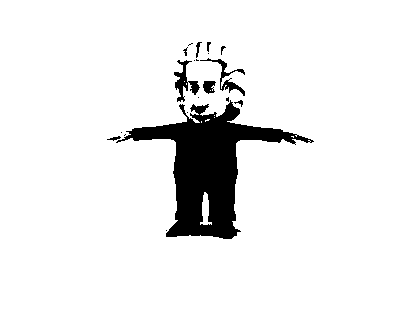

im = imread('data\einstein.jpg');
imBW = im2bw(im,.7);
figure;
imshow(imBW)

## Generate TX Data

clear;

%choose a picture
picture = 'einstein';

%define whether or not you want to include hamming error correction
hamming_on = 0;

%generate start sequence
input_image = strcat('data\',picture,'.jpg');
pilot_seq_len = 32; % (length of known pilot sequence)/2
standard_packet_len = 100000;
Fs = 2000000; % sampling frequency

%generate RRC Pulse
T = 50; % Symbol Period
data_len = standard_packet_len * T;
span = 20;
rolloff = 0.5;
rrc = rcosdesign(rolloff,span,T, 'sqrt');   % creates a root-raised cosine 

[imBW,dataQ,data] = image_to_data(input_image,hamming_on);

if hamming_on
    txname = strcat('data\', picture, '_hamming.dat');
else
    txname = strcat('data\', picture, '.dat');
end
txname

txname = 'data\einstein.dat'

input = build_tx_file(txname, dataQ, pilot_seq_len, rrc, T, standard_packet_len)

input =   -0.7968 + 0.8074i
  -0.7878 + 0.7984i
  -0.7762 + 0.7867i
  -0.7621 + 0.7725i
  -0.7456 + 0.7557i
  -0.7266 + 0.7364i
  -0.7052 + 0.7145i
  -0.6815 + 0.6902i
  -0.6553 + 0.6634i
  -0.6270 + 0.6343i


## Decode RX Data

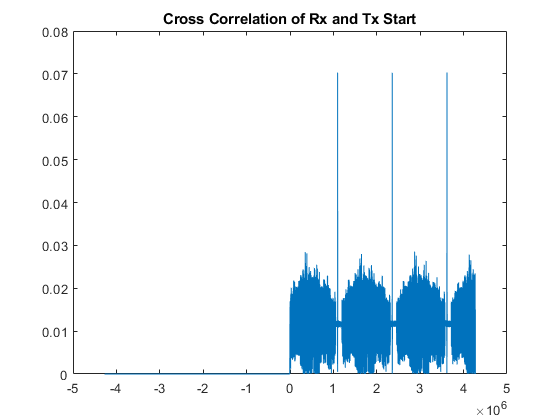

tx_pilot =   -0.1281 + 0.1298i
  -0.1266 + 0.1283i
  -0.1248 + 0.1265i
  -0.1225 + 0.1242i
  -0.1199 + 0.1215i
  -0.1168 + 0.1184i
  -0.1134 + 0.1149i
  -0.1095 + 0.1109i
  -0.1053 + 0.1066i
  -0.1008 + 0.1020i


startPos = 3616568

startPos = 3616568

rx_pilot = 	1.0e+-3 *

  -0.3967 + 0.4578i
  -0.1526 + 0.4883i
   0.0916 + 0.3052i
   0.0916 + 0.0000i
  -0.0610 - 0.1526i
  -0.2747 - 0.1526i
  -0.5799 + 0.0000i
  -0.5493 + 0.2441i
  -0.2747 + 0.3052i
  -0.1831 + 0.1831i


a =    0.9979 - 0.0647i
   0.8889 - 0.4581i
   0.4800 - 0.8773i
  -0.7023 - 0.7119i
  -0.4001 + 0.9165i
   0.2683 + 0.9633i
   0.7025 + 0.7117i
   0.9310 + 0.3649i
   0.9989 - 0.0465i
   1.0000 + 0.0058i


diff = 0.2153

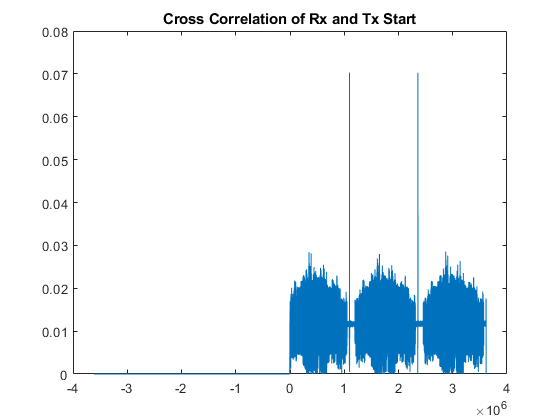

tx_pilot =   -0.1281 + 0.1298i
  -0.1266 + 0.1283i
  -0.1248 + 0.1265i
  -0.1225 + 0.1242i
  -0.1199 + 0.1215i
  -0.1168 + 0.1184i
  -0.1134 + 0.1149i
  -0.1095 + 0.1109i
  -0.1053 + 0.1066i
  -0.1008 + 0.1020i


startPos = 1096974

startPos = 1096974

rx_pilot =   -0.5188 - 0.0916i
  -0.4578 + 0.0305i
  -0.2136 + 0.0610i
  -0.1221 + 0.0000i
  -0.2441 - 0.0610i
  -0.5188 - 0.1221i
  -0.5799 + 0.0610i
  -0.5188 + 0.3662i
  -0.2441 + 0.3967i
   0.0305 + 0.1526i


a =    0.5680 + 0.8230i
   0.7482 + 0.6635i
   0.8709 + 0.4915i
   0.7023 + 0.7119i
   0.5087 + 0.8609i
   0.5207 + 0.8538i
   0.7731 + 0.6343i
   0.9844 + 0.1762i
   0.9742 - 0.2257i
   0.5595 - 0.8288i


diff = 0.5901

Index exceeds the number of array elements (3172556).

Error in qpsk (line 40)
    signal_rx = conv(read_shifted(1:packet_length-pilot_sequence_len*T),rrc,'same');

txname='data\einstein_2million.dat';
rxname = 'data\rx_einstein_2million.dat';
figure;
[rxQ, errRate] = qpsk(txname, rxname, T, 2000000, data_len);   

errRate

## Printing Image

%Transfrom QAM into binary
rxQ = sign(real(rxQ)) + 1i*sign(imag(rxQ));
rxBinary = decodeQam(rxQ);

%Perform Error Correction
if hamming_on
    rxBinary = errorCorrect(rxBinary);
end

%retreive rows and columns
rows = bi2de(rxBinary(1:16),'left-msb');
cols = bi2de(rxBinary(17:32),'left-msb');

%fix odd length data error
if mod(rows*cols,2) ~= 0
    dataRx = rxBinary(33:end-1);
else
    dataRx = rxBinary(33:end);
end
dataRx = dataRx(1:216*233)
%compute error after hamming decoding
compute_qpsk_error(data,dataRx)
%plot image
rxIm = reshape(dataRx, 216, []);
figure;
subplot(1,2,1)
imshow(rxIm)
subplot(1,2,2)
imshow(imBW)